clearvars; clc;

E = 1000.0

E = 1000

E_T = 40.0

E_T = 40

sigma_0 = 1

sigma_0 = 1

theta = 1

theta = 1

eta = 2000

eta = 2000

t1 = 6

t1 = 6

c = 0.03/t1

c = 0.0050

H = (E*E_T)/(E-E_T)

H = 41.6667

syms t

epsilon = c*t

$$epsilon = 0.0050\,t$$

epsilon_0 = sigma_0/E

epsilon_0 = 1.0000e-03

tau = eta/(E+H)

tau = 1.9200

epsilon_star = c*tau

epsilon_star = 0.0096

t_start = epsilon_0/c

t_start = 0.2000

t_end = 6*t1

t_end = 36


sigma = sigma_0 + E_T*(epsilon - epsilon_0) + (E-E_T)*epsilon_star*(1-exp(-(epsilon-epsilon_0)/epsilon_star))

$$sigma = 0.2000\,t-9.2160\,{\mathrm{e}}^{0.1042-0.5208\,t}+10.1760$$

epsilon_vp = (1-E_T/E)*(-epsilon_star*(1-exp(-(epsilon-epsilon_0)/epsilon_star))+epsilon-epsilon_0)

$$epsilon\_vp = 0.0048\,t+0.0092\,{\mathrm{e}}^{0.1042-0.5208\,t}-0.0102$$

folderPath = "D:\MTechDesign\Sem4\ME759_NonlinearFEM\Codes\Assignment3\"

folderPath = "D:\MTechDesign\Sem4\ME759_NonlinearFEM\Codes\Assignment3\"

fileName = "fortran_code_output.csv"

fileName = "fortran_code_output.csv"

fullFilePath = folderPath + fileName

fullFilePath = "D:\MTechDesign\Sem4\ME759_NonlinearFEM\Codes\Assignment3\fortran_code_output.csv"

% Ref: https://nl.mathworks.com/help/matlab/ref/readtable.html
T = readtable(fullFilePath,"VariableNamingRule","preserve");
T([1,2,3,4],:) = [];
T(T.("Integration Point") == 2,:)=[];
height(T)

ans = 718

sigma_e = E*epsilon

$$sigma\_e = 5\,t$$

sigma_pw = piecewise(epsilon<=epsilon_0,sigma_e,epsilon>epsilon_0,sigma)

$$sigma\_pw = \left\{ \begin{array}{cl} 5\,t & \text{ if }t\leq 0.2000\\ 0.2000\,t-9.2160\,{\mathrm{e}}^{0.1042-0.5208\,t}+10.1760 & \text{ if }0.2000<t \end{array}\right.$$

epsilon_analy = subs(epsilon,t,T.Time);
sigma_analy = subs(sigma_pw,t,T.Time);

v_anal = [epsilon_analy, sigma_analy];
v_FEM = [T.("Total Strain"), T.Stress];
str_norm = sprintf("L2-norm between analytical and FEM results: %f", 0.2873)

str_norm = "L2-norm between analytical and FEM results: 0.287300"

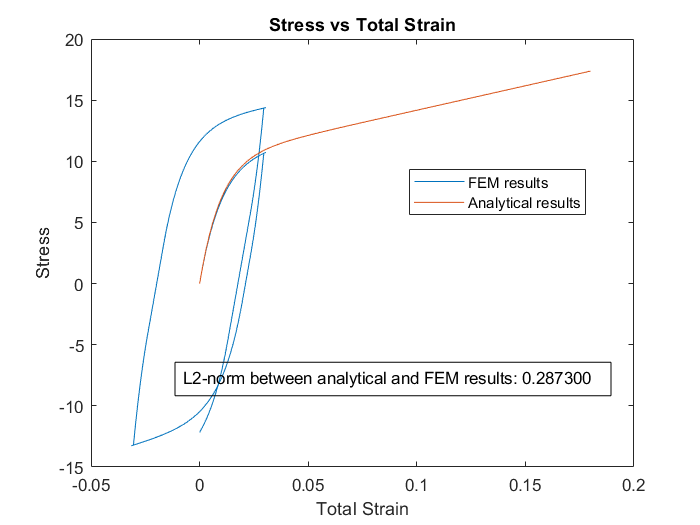

% Stress vs Total Strain
% Ref: https://nl.mathworks.com/help/matlab/ref/fplot.html#d123e472623
figure
plot(T.("Total Strain"), T.Stress)
hold on
fplot(epsilon,sigma_pw,[0 t_end])
dim = [.25 .01 .3 .3];
annotation('textbox',dim,'String',str_norm,'FitBoxToText','on');
hold off

xlabel("Total Strain")
ylabel("Stress")
title("Stress vs Total Strain")
legend("FEM results", "Analytical results", "Location","best")

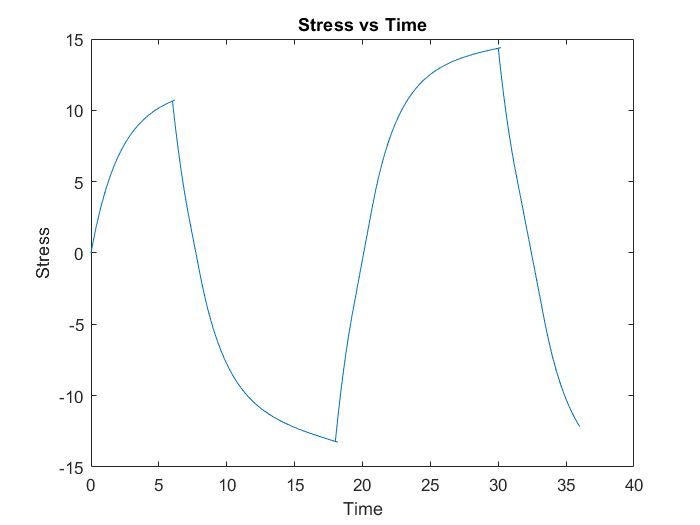

% Stress vs Time
plot(T.Time, T.Stress)
xlabel("Time")
ylabel("Stress")
title("Stress vs Time")

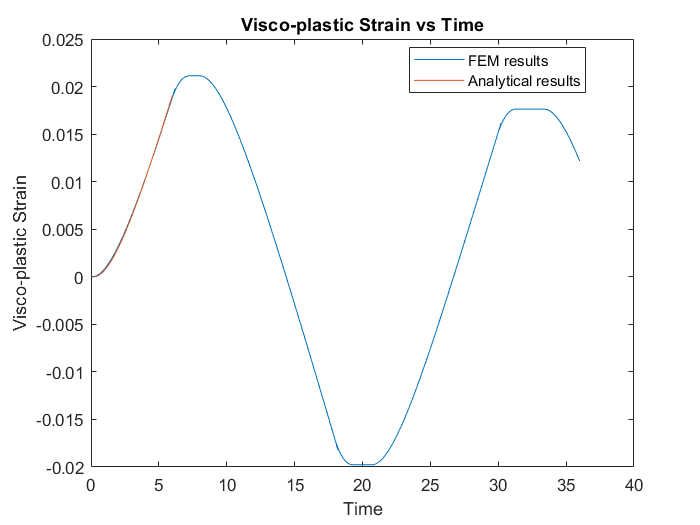

% Visco-plastic Strain vs Time
plot(T.Time, T.("Visco-plastic Strain"))
hold on
fplot(epsilon_vp,[t_start t1])
hold off
xlabel("Time")
ylabel("Visco-plastic Strain")
title("Visco-plastic Strain vs Time")
legend("FEM results", "Analytical results", "Location","best")

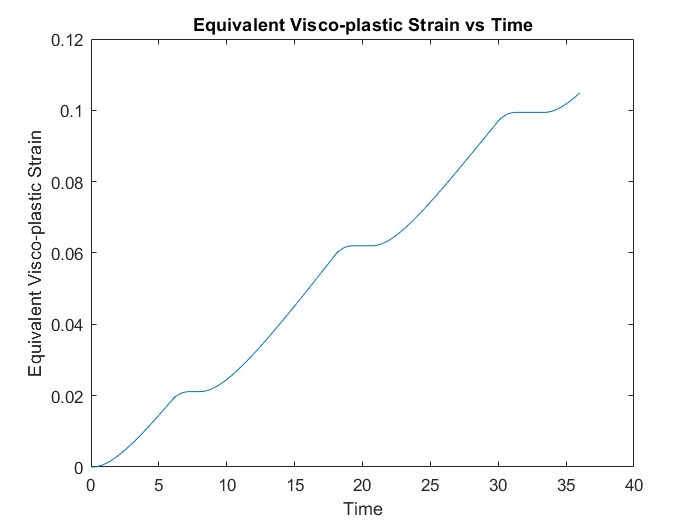

% Equivalent Visco-plastic Strain vs Time
plot(T.Time, T.("Equivalent viscoplastic Strain"))
xlabel("Time")
ylabel("Equivalent Visco-plastic Strain")
title("Equivalent Visco-plastic Strain vs Time")

## For t = 6 * t1

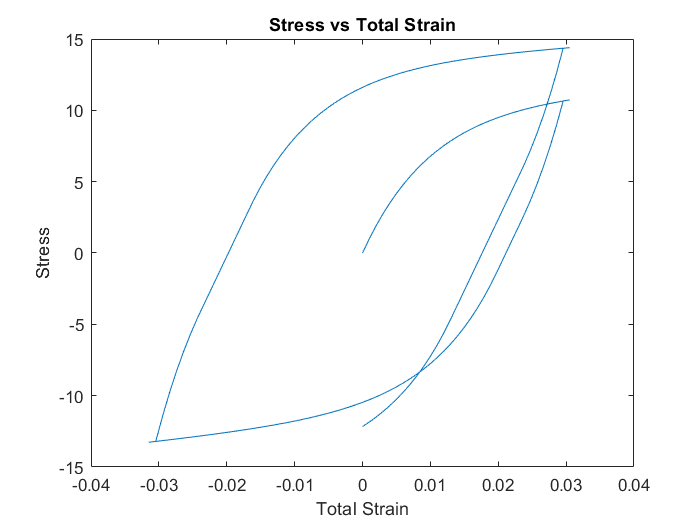

% Stress vs Total Strain
% Ref: https://nl.mathworks.com/help/matlab/ref/fplot.html#d123e472623
figure
plot(T.("Total Strain"), T.Stress)

xlabel("Total Strain")
ylabel("Stress")
title("Stress vs Total Strain")

% % Stress vs Vicoplastic Strain
% plot(T.("Visco-plastic Strain"), T.Stress)
% hold on
% fplot(epsilon_vp,sigma_vp, [t_start t_end])
% hold off
% xlabel("Visco-plastic Strain")
% ylabel("Stress")
% title("Stress vs Visco-plastic Strain")
% legend("FEM results", "Analytical results", "Location","best")

% % Stress vs Time
% plot(T.Time, T.Stress)
% hold on
% fplot(sigma,[t_start t_end])
% hold off
% xlabel("Time")
% ylabel("Stress")
% title("Stress vs Time")
% legend("FEM results", "Analytical results", "Location","best")

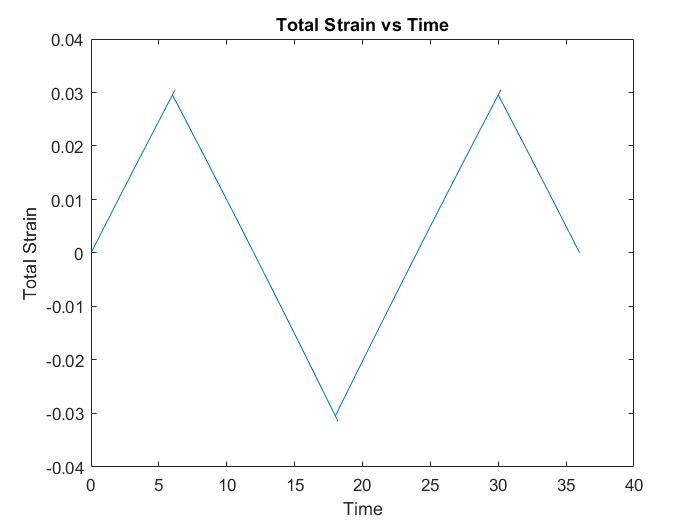

% Total Strain vs Time
plot(T.Time, T.("Total Strain"))
xlabel("Time")
ylabel("Total Strain")
title("Total Strain vs Time")

% % Back Stress vs Total Strain
% plot(T.("Total Strain"), T.("Back Stress"))
% xlabel("Total Strain")
% ylabel("Back Stress")
% title("Back Stress vs Total Strain")

% % Yield Stress vs Time
% plot(T.Time, T.("Yield Stress"))
% xlabel("Time")
% ylabel("Yield Stress")
% title("Yield Stress vs Time")

% % Yield Stress vs Equivalent plastic strain
% plot( T.("Equivalent Plastic Strain"),T.("Yield Stress"))
% xlabel("Equivalent Plastic Strain")
% ylabel("Yield Stress")
% title("Yield Stress vs Equivalent plastic strain")

% % Back Stress vs Equivalent plastic strain
% plot( T.("Equivalent Plastic Strain"),T.("Back Stress"))
% xlabel("Equivalent Plastic Strain")
% ylabel("Back Stress")
% title("Back Stress vs Equivalent plastic strain")